clear all
close all

%Define initial values of variables
x_initial = [50, 20, 10, 32, 100, 205, 12, 300, 120, 250, 56, 73, 15, 30, 10, 8, 50000000, 0.5, 20, 80, 44]

x_initial = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

% % %load earthquake data for 6 months in japan (9/27/2024 ~ 3/26/2025)
% earthquake_data_sorted = load("earthquake_data_sorted.mat");
% data = earthquake_data_sorted.earthquakes;

%test costObj function
[totalCost] = costObj(x_initial)

totalCost = single
943209216

%Run GA

%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [0,0,0,0,0,0,0,0,0,0,0,0];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      0     0     0     0     0     0     0     0     0     0     0     0    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000


%%% Set GA parameters - note: this code hasn't been tested
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; %this seems wrong? i thought 17 was part of train optimization (should be 16?)
nvars = 21;
nonlincon = @combinedNonlincon;
fun = @costObj;

%Vmax_placeholder = 10;
%numcars_placeholder = 16;

%setGlobalVars(Vmax_placeholder,numcars_placeholder)

%intcon for network and safety 
intcon_network = [1, 2, 3, 4,5, 6, 7,8,9,10,11,12,16];
intocon_train = [4];

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', true, ...                        % faster evals
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 120, ...
    'FunctionTolerance', 1e-3, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-3, ...                % tight, but not zero, tolerance on constraints
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);


Single objective optimization:
21 Variables
13 Integer variables
51 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible
Starting parallel pool (parpool) using the 'Processes' profile ...
Parallel pool using the 'Processes' profile is shutting down.



%calculate individual scores
convenience_score = networkScore(x_star(1:12))

convenience_score = single
-0.3818

train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))

train_veloc = 69.6643

number_of_accidents = accident_count_function(x_star(16:21))

number_of_accidents = 0.9953


fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))

network_cost = single
487356448

train_cost = TrainCost(x_star(16))

train_cost = 105000000

safety_cost = safety_system_cost_function(x_star(17:21))

safety_cost = 6.2053e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   487356448   105000000   620531136



Single objective optimization:
21 Variables
13 Integer variables
51 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible



                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.5113           1.083        0
    2              360          0.3663          0.8216        0
    3              480          0.2626          0.6004        0
    4              600          0.2152          0.5239        0
    5              720          0.1673          0.4173        0
    6              840          0.1673          0.3579        1
    7              960          0.1555          0.2986        0
    8             1080          0.1145           0.242        0
    9             1200          0.1145          0.2813        1
   10             1320          0.1073          0.2306        0
   11             1440          0.0915          0.2011        0
   12             1560         0.06764          0.1994        0
   13             1680         0.05441          0.1821        0
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.5343           1.149        0
    2              360          0.5022          0.8593        0
    3              480          0.4734          0.7131        0
    4              600          0.4534          0.6381        0
    5              720          0.4036          0.5985        0
    6              840          0.4029          0.5587        0
    7              960          0.3734          0.5212        0
    8             1080          0.3734          0.5166        1
    9             1200           0.267           0.556        0
   10             1320          0.2282          0.4467        0
   11             1440          0.2282          0.4236        1
   12             1560          0.2272          0.3763        0
   13             1680          0.1719          0.3008        0
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.3076           1.198        0
    2              360           0.289          0.8542        0
    3              480          0.2701          0.6579        0
    4              600          0.1511          0.5285        0
    5              720          0.1493          0.4457        0
    6              840          0.1385          0.3524        0
    7              960          0.1349          0.3114        0
    8             1080          0.1323          0.2744        0
    9             1200          0.1177          0.2379        0
   10             1320          0.0949          0.2351        0
   11             1440         0.09486          0.2152        0
   12             1560         0.08337          0.1934        0
   13             1680         0.08337          0.1599        1
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.5113           1.139        0
    2              360          0.5103          0.9456        0
    3              480          0.3213          0.7266        0
    4              600          0.3193          0.6129        0
    5              720           0.189          0.5116        0
    6              840           0.189          0.4623        1
    7              960          0.1833          0.4461        0
    8             1080          0.1535          0.3513        0
    9             1200         0.07799           0.319        0
   10             1320         0.07799            0.26        1
   11             1440         0.07799          0.2439        2
   12             1560         0.04214          0.2062        0
   13             1680         0.04214          0.1823        1
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.6036           1.229        0
    2              360          0.4717          0.9459        0
    3              480          0.3544          0.7529        0
    4              600          0.3381          0.6708        0
    5              720          0.3148          0.5586        0
    6              840          0.2315          0.5025        0
    7              960          0.1763          0.4436        0
    8             1080          0.1597          0.3684        0
    9             1200          0.1597          0.2901        1
   10             1320          0.1432          0.3053        0
   11             1440           0.109          0.2246        0
   12             1560           0.109          0.2267        1
   13             1680           0.109          0.2299        2
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.4706          0.9979        0
    2              360          0.4624          0.8222        0
    3              480          0.3202          0.6915        0
    4              600          0.1611          0.5994        0
    5              720          0.1611          0.5371        1
    6              840          0.1611          0.4605        2
    7              960          0.1571          0.4151        0
    8             1080          0.1256          0.3456        0
    9             1200          0.1256          0.2586        1
   10             1320          0.1256          0.2556        2
   11             1440          0.1256          0.2662        3
   12             1560          0.1256          0.2818        4
   13             1680          0.1187          0.2515        0
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.4307           1.028        0
    2              360          0.2195          0.8145        0
    3              480           0.218          0.6936        0
    4              600          0.1705          0.4978        0
    5              720         0.09768          0.3955        0
    6              840         0.09768          0.3363        1
    7              960          0.0723          0.3028        0
    8             1080          0.0452          0.2132        0
    9             1200          0.0452          0.2301        1
   10             1320          0.0452          0.1918        2
   11             1440         0.04292          0.2762        0
   12             1560         0.03522          0.1202        0
   13             1680         0.03519          0.1414        0
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.3339           1.067        0
    2              360           0.318          0.7961        0
    3              480          0.1955           0.573        0
    4              600           0.126          0.4375        0
    5              720           0.125          0.3617        0
    6              840          0.1239          0.3048        0
    7              960          0.1036           0.266        0
    8             1080         0.09698          0.2319        0
    9             1200         0.07439          0.1981        0
   10             1320         0.07439          0.1378        1
   11             1440         0.07439          0.1458        2
   12             1560         0.04493          0.1648        0
   13             1680         0.04493          0.1223        1
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.6415           1.204        0
    2              360          0.4041           1.057        0
    3              480          0.3792          0.8228        0
    4              600          0.3086          0.6782        0
    5              720          0.2975          0.6262        0
    6              840          0.2372          0.5517        0
    7              960          0.1983          0.4688        0
    8             1080          0.1625          0.3864        0
    9             1200          0.1284          0.3332        0
   10             1320         0.07357          0.2853        0
   11             1440         0.04724          0.2295        0
   12             1560         0.04465          0.2236        0
   13             1680         0.04465          0.1625        1
   14             1800        

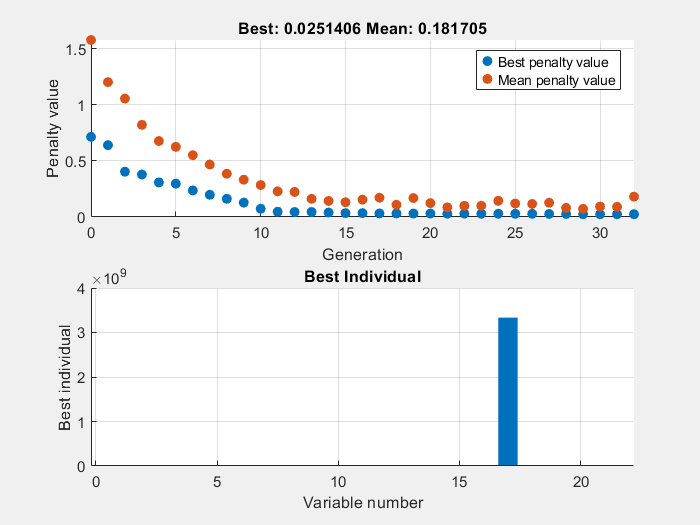

%Sensitivity Analysis parameter sweep
%Sensitivity coefficients give the rate of change of the optimal values of
%the objective relative to small changes in the values of the constraints

% Constraints to sweep:
% Government Study comes out on train safety causing a mandate to regulate all train maximum speeds to ___.
% Government grant comes out for public transport, all costs to build stations are now halved.
% earthquake warning speed

%need to set these values
% [maxV, dist, warningSpeed]
maxV = 0;
dist = 0;
warningSpeed = 0;

setGlobalConstraintVars(maxV, dist, warningSpeed)

nonlincon = @combinedNonlinconSensitivityTesting;

%sweep maxV, hold c and warningSpeed constant
x_star_sweep_dist = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_dist = [];
sweep_vals_dist = [];

for i = 20:5:60
    %set constraint values
    setGlobalConstraintVars(maxV, i, warningSpeed)

    %run GA
    [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
    
    %save values
    x_star_sweep_dist(end+1,:) = x_star;
    fval_sweep_dist(end+1) = fval;
    sweep_vals_dist(end+1) = i;
end


% --- copy for every other constrain sweep once it works ---



%plot values
figure()
plot(sweep_vals_dist,fval_sweep_dist)

Unrecognized function or variable 'sweep_vals_dist'.

xlabel("Minimum Distance Between Stations (km)")
ylabel("totalCost")

% %shared variables are: 
% %Output from safety optimization: Vmax (x(21)) --> input to train optimizer
% %Output from train optimization: number of cars (gives mass) (x(16)) ---> parameter in safety optimization 
% 
% %network: (x(1:12))
% %train: (x(13:16))
% %safety: (x(17:21))
% 
% %FPI/MDF:
% %First iteration:
% %set initial placeholders for shared variables
% Vmax_placeholder = 10;
% numcars_placeholder = 16;
% 
% setGlobalVars(Vmax_placeholder,numcars_placeholder)
% %r = getGlobalVars; %for testing 
% 
% % add to beginnning of functions as necessary:
% % [r1, r2] = getGlobalVars;
% % numberofcars = r2;
% % Vmaximum = r1;
% 
% %set epselom (to tune)
% epselom = 0.0001;
% 
% %run GA on network
% [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
% 
% %run GA on train
% [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
% %run GA on safety (should be no intcon for this subsystem)
% [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% 
% %enter while loop, compare placeholder to calculated values
% %If not same, iterate until they converge
% while (((Vmax_placeholder - Vmax) > epselom) && ((numcars_placeholder - numcars) > epselom));
%     %reset placeholer values to last calculated value
%     Vmax_placeholder = x_safety(5);
%     numcars_placeholder = x_train(4);
%     setGlobalVars(Vmax_placeholder,numcars_placeholder);
% 
%     %run GA on network
%     [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
%     
%     %run GA on train
%     [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
%     %run GA on safety (should be no intcon for this subsystem)
%     [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% end
% 
% %combine for overall x_star and calculate total cost
% x_star = [x_network, x_train, x_safety]
% total_cost = costObj(x_star)



